# derive_equations_JR.m

Description: Symbolically derive equations related to the jumping robot, including the full nonlinear state-space dynamics.

Inputs: none

Outputs: none

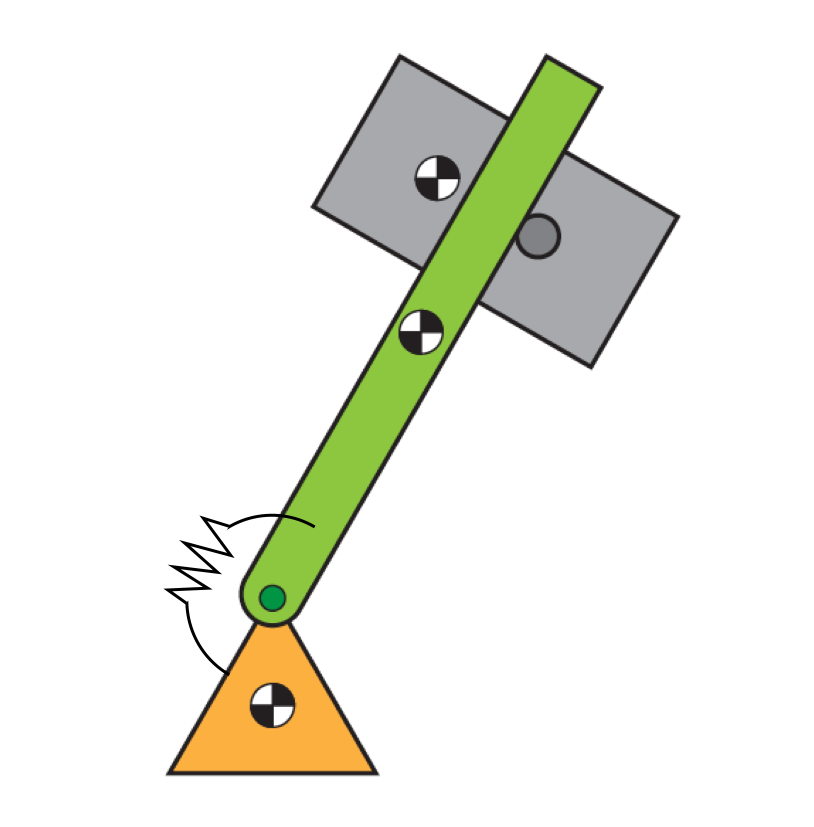

clearvars;
close all;
clc;

fprintf('Deriving jumping robot equations...\n');

## Variable definition

 This version is used for balancing control.  There are only three generalized coordinates: theta_f, theta_s, and theta_m.  The left foot is assumed to be constrained to slide along the floor and all equations are written in a frame that moves in the x direction with the COM

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

% Generalized coordinates:
% theta_f: angle of the foot relative to ground; positive cw
% theta_s: angle of the spine relative to foot; positive cw
% theta_m: angle of the motor; positive ccw
syms theta_f theta_s theta_m real
q = [theta_f; theta_s; theta_m];

% Generalized velocities:
syms theta_dot_f theta_dot_s theta_dot_m real
q_dot = [theta_dot_f; theta_dot_s; theta_dot_m]

% Generalized accelerations:
syms theta_ddot_f theta_ddot_s theta_ddot_m real
q_ddot = [theta_ddot_f; theta_ddot_s; theta_ddot_m]

% Generalized forces:
% tau_s: torque at base of spine; positive cw
% tau_m: motor torque on body motor; positive ccw
syms tau_s tau_m real 
Q = [0; tau_s; tau_m];

fprintf('\t...done.\n');

## Inertial (and other) parameters

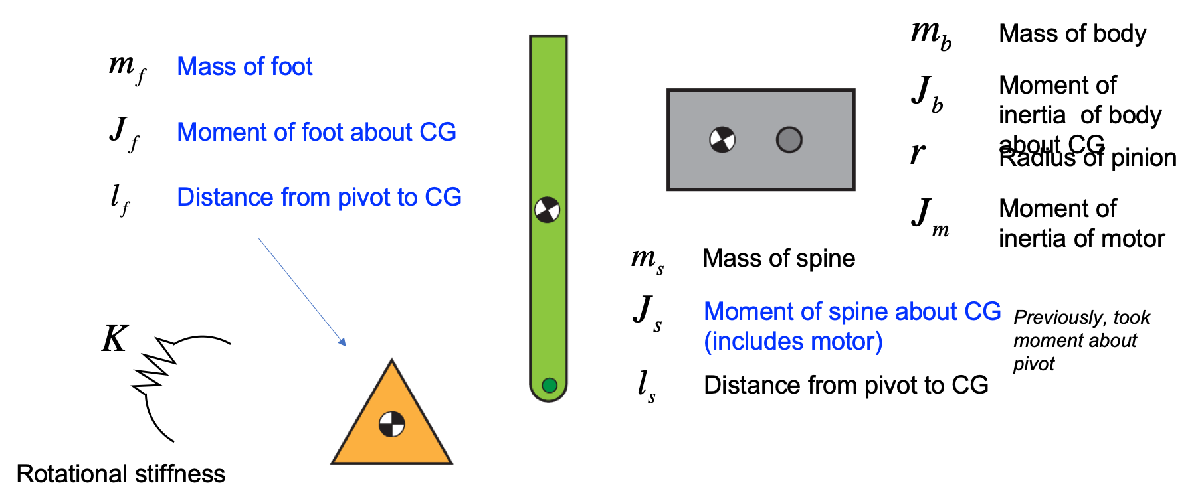

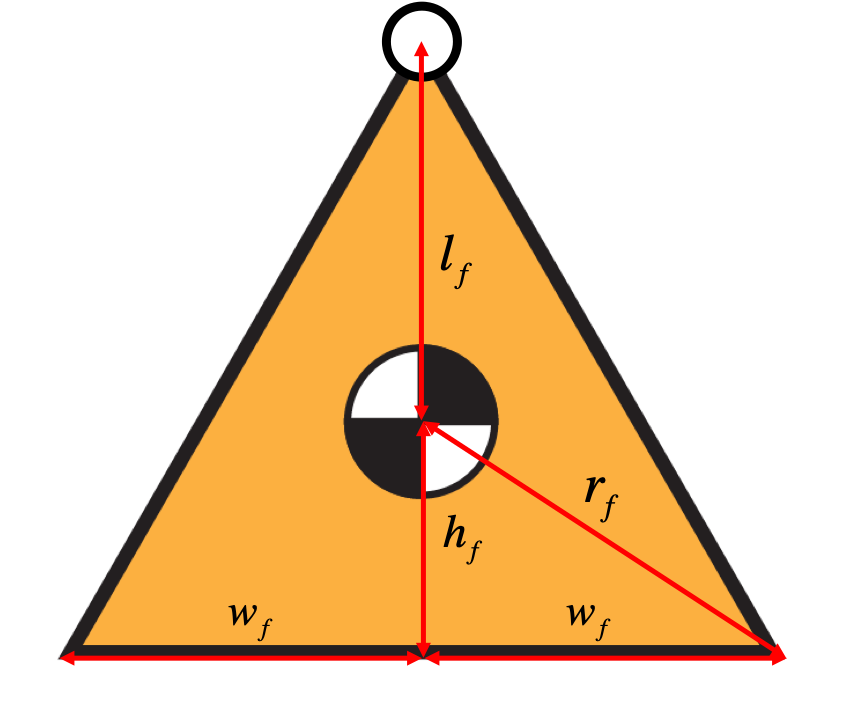

A couple of other parameters include h_b, the height of the body, and l_spine, the length of the spine.

fprintf('\tInitializing inertial (and other) parameters...\n');

% Mass of each body:
syms m_f m_s m_b real

m_all = m_f + m_s + m_b;

% Rotational inertia of each component:
syms J_f J_s J_b J_m real

% Stiffness between sping and foot:
syms K real

% Geometry:
syms l_s h_b r h_f w_f l_f l_spine real

% Other variables
g = sym('g','real'); % gravity
% t = sym('t','real'); % time

fprintf('\t...done.\n');

## CoM Forward Kinematics

Here the goal is to find the CoM motion for each body (relative to the system CoM in the x direction, and the floor in the z-direction.

fprintf('\tInitializing kinematics variables...\n');

% x and z coordinates of the spine and body CoM:
syms x_f z_f x_s z_s x_b z_b real

x_f = (m_s + m_b)*l_f*sin(theta_f)/m_all + (m_s*l_s + m_b*r*theta_m)*sin(theta_f + theta_s)/m_all;
z_f = w_f*sin(theta_f) + h_f*cos(theta_f);
x_s = ((m_s + m_b)/m_all - 1)*l_f*sin(theta_f) + ((m_s*l_s + m_b*r*theta_m)/m_all - l_s)*sin(theta_f + theta_s);
z_s = z_f + l_f*cos(theta_f) + l_s*cos(theta_f + theta_s);
x_b = ((m_s + m_b)/m_all - 1)*l_f*sin(theta_f) + ((m_s*l_s + m_b*r*theta_m)/m_all - r*theta_m)*sin(theta_f + theta_s);
z_b = z_f + l_f*cos(theta_f) + r*theta_m*cos(theta_f + theta_s);

% create 2x1 arrays to hold the CoM forward kinematics (FK) outputs:
FK_com_f = [x_f; z_f];
FK_com_s = [x_s; z_s];
FK_com_b = [x_b; z_b];

% x coordinate of the left wheel
syms x_wheel real

x_wheel = x_f - w_f*cos(theta_f) + h_f*sin(theta_f);

% equilibrium motor angle
syms theta_m_eq real

temp1 = ( w_f*cos(theta_f) - ((m_s + m_b)*l_f/m_all + h_f)*sin(theta_f) ) / sin(theta_f + theta_s);
theta_m_eq = simplify( (m_all*temp1 - m_s*l_s) / (m_b * r) );

% coordinates of the pivot and the spine tip to help animate
syms x_pivot z_pivot x_tip z_tip real

x_pivot = x_f - l_f*sin(theta_f);
z_pivot = z_f + l_f*cos(theta_f);
x_tip = x_f - l_f*sin(theta_f) - l_spine*sin(theta_f + theta_s);
z_tip = z_f + l_f*cos(theta_f) + l_spine*cos(theta_f + theta_s);

% create 2x1 arrays to hold the Visualization forward kinematics (FK) outputs:
FK_pivot = [x_pivot; z_pivot];
FK_tip = [x_tip; z_tip];

fprintf('\t...done.\n');
fprintf('\tGenerating forward kinematics equations...\n');

% generate MATLAB functions to compute all the FK outputs:
matlabFunction(x_wheel,'File','autogen_wheel_position');
matlabFunction(theta_m_eq,'File','autogen_equilibrium_motor_angle');
matlabFunction(FK_com_f,FK_com_s,FK_com_b,'File','autogen_fk_com');
matlabFunction(FK_pivot,FK_tip,'File','autogen_fk_viz');
% Note: these autogenerated functions will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

## Constraint Equations

none!

## Derivatives

Here we take derivatives of both the forward kinematics and the constraint equations

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

syms dFK_com_f dFK_com_s dFK_com_b A_all H_clx H_clz H_crx H_crz real

% Body CoM velocities:
dFK_com_f = jacobian(FK_com_f,q)*q_dot
dFK_com_s = jacobian(FK_com_s,q)*q_dot
dFK_com_b = jacobian(FK_com_b,q)*q_dot

% generate MATLAB functions for the Jacobians and Hessians:
matlabFunction(dFK_com_f,dFK_com_s,dFK_com_b,'File','autogen_jacobians');

fprintf('\t...done.\n');

## Kinetic energy

Sum up:

- Foot translational

- Foot rotational

- Spine translational

- Spine rotational

- Body translational

- Body rotational

- Motor rotational

fprintf('\tGenerating kinetic energy equation...\n');

syms ke_f ke_s ke_b KE real

% kinetic energy of each body:
ke_f = 0.5*J_f*theta_dot_f^2 + 0.5*m_f*(dFK_com_f'*dFK_com_f);
ke_s = 0.5*J_s*(theta_dot_f + theta_dot_s)^2 + 0.5*m_s*(dFK_com_s'*dFK_com_s);
ke_b = 0.5*J_b*(theta_dot_f + theta_dot_s)^2 + 0.5*m_b*(dFK_com_b'*dFK_com_b) + 0.5*J_m*(theta_dot_m + theta_dot_f + theta_dot_s)^2;

% total kinetic energy:
KE = ke_f + ke_s + ke_b

fprintf('\t...done.\n');

## Potential energy

Sum up:

- Gravitational potential of foot

- Gravitational potential of spine

- Gravitational potential of body

- Spring

Note:  does not include virtual work done by constraints

fprintf('\tGenerating potential energy equation...\n');

syms pe_f pe_s pe_b pe_spring real

% potential energy of each body:
pe_f = m_f*g*(z_f - h_f);
pe_s = m_s*g*(z_s - l_s - l_f - h_f);
pe_b = m_b*g*(z_b - l_f - h_f);
pe_spring = 0.5*K*theta_s^2;

% total potential energy:
PE = pe_f + pe_s + pe_b + pe_spring

% generate Matlab function for total energy
matlabFunction(KE,PE,'File','autogen_energy');

fprintf('\t...done.\n');

## Euler-Lagrange equations

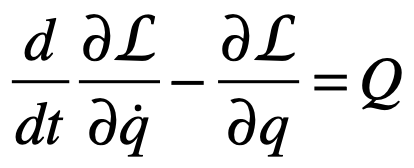

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

% Variable initializations:
del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_qdot = jacobian(KE,q_dot)';
ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;q_dot])*[q_dot;q_ddot])
ELeq_term2 = simplify(jacobian((KE-PE),q))'
% Note: no constraint forces yet

fprintf('\t...done.\n')

## Finding the mass matrix and H(q,q_dot)

Note: the highest order derivative that shows up in the Euler-Lagrange Equations is second:  q_ddot  (accelerations).  Our goal is to obtain equations for q_ddot in terms of the state q, state derivatives q_dot, and generalized forces (i.e., the motor torques) Q.  These equations can then be integrated forward in time.  Fortunately, the accelerations always show up linearly and the matrix that multiplies them, the "mass matrix" is guaranteed to be invertible:

      M(q)*q_ddot + H(q,q_dot) = Q

Note that this equation is a generalization of F=ma. It represents the *inverse* dynamics, mapping positions, velocities, and accelerations of the joints to forces or torques (depending on the nature of each joint).

Important note:  there is additional structure in H that is often important to know about.  We won't go into that here.

fprintf('\tSolving for the mass matrix...\n');

M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');

M = simplify(jacobian(del_L_del_qdot,q_dot))
H = simplify(jacobian(del_L_del_qdot,q)*q_dot - ELeq_term2)
G_q = simplify(jacobian(PE,q))

fprintf('\t\t...done building M and H.\n');


## Finding the inverse mass matrix

Note: we need inv(M) to compute the fwd. dynamics and therefore the state-space dynamics (see below), so to ease computation cost we derive inv(M) symbolically here and autogenerate a dedicated MATLAB function for evaluating it.


% compute and store inv(M):
% fprintf('\t\tComputing inv(M)...\n')
% Minv = sym('Minv',[numel(q),numel(q)],'real');
% Minv = simplify(inv(M))
% fprintf('\t\t...done.\n')
% 
fprintf('\t\tGenerating MATLAB functions...\n');
matlabFunction(M,'File','autogen_mass_matrix');
% matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H_eom');
matlabFunction(G_q,'File','autogen_conservative_forces');
fprintf('\t\t...done.\n');

## Linearizing state equations

%% Linearize the state-space model around some stationary upright equilibrium
fprintf('\tLinearizing the dynamics about a stationary upright equilibrium...\n')
% Here's where we are:  the nonlinear state equations are:
%
%   M(q)*q_ddot = [0,0;eye(2)]*u - C(q,q_dot)*q_dot - G(q)
%
% At equilibrium, both q_ddot and q_dot are zero.  We can call the
% equilibrium of the generalized coordinates q_eq and of the controls u_eq:
%
%   M(q_eq)*0 = [0,0;eye(2)]*u_eq - C(q_eq,0)*0 - G(q_eq)
%
% thus:   0 = [0,0;eye(2)]*u_eq - G(q_eq)
%
% When we linearize about this equilibrium, we get the following (where
% we've taken advantage of the fact that all terms in C(q,q_dot)*q_dot are
% second order in q_dot.  Since we're taking equilibrium about q_dot = 0,
% the linearization of C is zero.
%
%   M(q_eq + q_lin)*q_lin_ddot = [0,0;eye(2)]*(u_eq + u_lin) - G(q_eq + q_lin)
%
% where q_lin and u_lin are small variations about the equilibrium.
% Therefore we can simplify as (keeping only terms up to first order):
%
%   M(q_eq)*q_lin_ddot = [[0,0;eye(2)]*u_eq - G(q_eq)] + [0,0;eye(2)]*u_lin - G_jac(q_eq)*q_lin
%
% which simplifies further to:
%
%   M(q_eq)*q_lin_ddot = [0,0;eye(2)]*u_lin - G_jac(q_eq)*q_lin
%
% Now we can write out linear state equations:
%
%   x_dot = [ 0,  I; -M(q_eq)\G_jac(q_eq), 0]*x + ...
%       M(q_eq)\[0,0;eye(2)]*u_lin

G_jac = simplify(jacobian(G_q,q)); % Jacobian of conservative forces

fprintf('\t...done linearizing the dynamics\n')

matlabFunction(G_jac,'File','autogen_derivative_conservative_forces');


## Done!

fprintf('...done deriving cart-pendulum equations.\n');
